%parametres needed for highpass butter function
Omega_c = pi/3;
Fs = 1000; % Sampling frequency (not specified in problem)
Fc = Omega_c/(Fs/2) % Cutoff frequency = Omega_c / (Sample frequecy/2) normalized

Fc = 0.0021

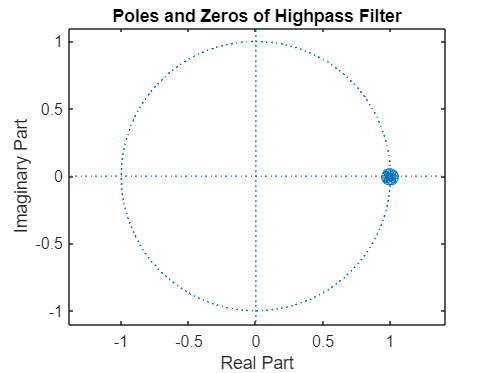

% Eighth-order digital highpass filter
[b_high, a_high] = butter(8, Fc, 'high');
figure;
zplane(b_high, a_high);
title('Poles and Zeros of Highpass Filter');

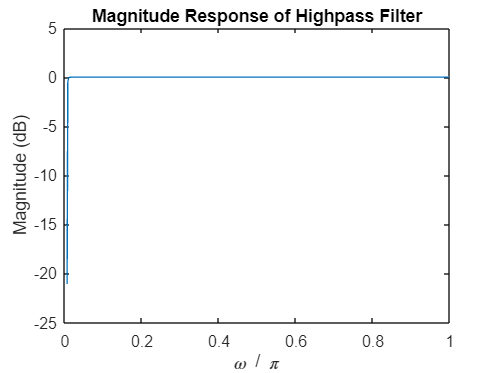


[h,w] = freqz(b_high,a_high);
dB = mag2db(abs(h)); %dB = 20 log10(|h|).
plot(w/pi,dB)
xlabel('\omega / \pi')
ylabel('Magnitude (dB)')
title('Magnitude Response of Highpass Filter');